# Hardpoint Forces Calculator

Original author: Graeme Dockrill, VDX sub-team member 2022

Modified by: Liam Foster, mechanical lead 2022-2024

Description: 

This script reads suspension hardpoints and input forces from the "Brightside V2 Suspension Geometry Design" Google Sheet, plots the suspension system in 3D, and calculates the forces in each member. It assumes a left corner from the driver's perspective and therefore the right wheels are outboard and see the most load. This is the consistent with the worst case scenario as the motor wheel is on the right and therefore seeing the most load possible.

% Clear the console and all variables
clear
clc

% Choose turn direction
TurnDir = -1;
% Choose loading in gs (*9.81m/s^2)
BrakeLoadCase = 1;
CornerLoadCase = 1;
BumpLoadCase = 2;

## Initialization & Data Pulling

% ----------------Setup----------------------------------------------------

% Constants
grav = 9.81; % [m/s^2]
hardpointsize = 10;
LineWidth = 1.5;
unitvect_scalefactor = 0.05;
unitvect_linewidth = 1.5;
forcevect_scalefactor = 0.00005;
forcevect_linewidth = 1.5;

% x,y,z for clearer equations
x = 1;
y = 2;
z = 3;

% Extracts balljoint coordinates from google sheets
ID = '1UxrHRz9iydKkYqhXAQWLDXY1FJoSzHCgv_TjBJgwtKQ';
sheet_name = 'Hardpoints';
url_name = sprintf('https://docs.google.com/spreadsheets/d/%s/gviz/tq?tqx=out:csv&sheet=%s',...
    ID, sheet_name);
data = webread(url_name);
masses = table(data{1:3,"X"},RowNames=data.Variable(1:3));
masses = renamevars(masses,"Var1","Mass");
masses{"m_Total","Mass"} = masses{"m_BS",:} + masses {"m_Driver",:};
X = data.X(4:39);
Y = data.Y(4:39);
Z = data.Z(4:39);
coords = table(X,Y,Z,RowNames=data.Variable(4:39));

% Converting values read from excel to 3D points
i = -3;
COM = coords(4+i,x:z);           % Center of mass
track = coords(5+i,x:z);         % Track width
wheelbase = coords(6+i,x:z);     % Wheelbase

lotusoffset = coords(7+i,x:z);   % Offset from origin to front tire contact patch
O = coords{8+i,x:z};             % Origin
MC = coords{9+i,x:z};            % Moment Center

% Front hardpoints
F_LCA_IR = coords{10+i,x:z};     % Front LCA inboard rear rod end
F_LCA_IF= coords{11+i,x:z};      % Front LCA inboard front rod end
F_LCA_O = coords{12+i,x:z};      % Front LCA outboard ball joint
F_UCA_IR = coords{13+i,x:z};     % Front UCA inboard rear rod end
F_UCA_IF = coords{14+i,x:z};     % Front UCA inboard front rod end
F_UCA_O = coords{15+i,x:z};      % Front UCA outboard ball joint
F_PR_O = coords{16+i,x:z};       % Front pull/push rod outboard rod end
F_PR_I = coords{17+i,x:z};       % Front pull/push rod inboard rod end
F_RP = coords{18+i,x:z};         % Front rocker pivot
F_RS = coords{19+i,x:z};         % Front rocker-shock mount
F_SC = coords{20+i,x:z};         % Front shock-chassis mount
F_TR_O = coords{21+i,x:z};       % Front steering tie-rod outboard rod end
F_TR_I = coords{22+i,x:z};       % Front steering tie-rod inboard rod end
F_WC = coords{23+i,x:z};         % Front wheel center
F_TP = coords{24+i,x:z};         % Front tire contact patch

% Rear hardpoints
R_LCA_IR = coords{25+i,x:z};     % Rear LCA inboard rear rod end
R_LCA_IF= coords{26+i,x:z};      % Rear LCA inboard front rod end
R_LCA_O = coords{27+i,x:z};      % Rear LCA outboard ball joint
R_UCA_IR = coords{28+i,x:z};     % Rear UCA inboard rear rod end
R_UCA_IF = coords{29+i,x:z};     % Rear UCA inboard front rod end
R_UCA_O = coords{30+i,x:z};      % Rear UCA outboard ball joint
R_PR_O = coords{31+i,x:z};       % Rear pull/push rod outboard rod end
R_PR_I = coords{32+i,x:z};       % Rear pull/push rod inboard rod end
R_RP = coords{33+i,x:z};         % Rear rocker pivot
R_RS = coords{34+i,x:z};         % Rear rocker-shock mount
R_SC = coords{35+i,x:z};         % Rear shock-chassis mount
R_TR_O = coords{36+i,x:z};       % Rear steering tie-rod outboard rod end
R_TR_I = coords{37+i,x:z};       % Rear steering tie-rod inboard rod end
R_WC = coords{38+i,x:z};         % Rear wheel center
R_TP = coords{39+i,x:z};         % Rear tire contact patch

% Creating matrices for each part for plotting purposes
F_LCA = coords{["F_LCA_IF","F_LCA_O","F_LCA_IR"],:};  % Front lower control arm
F_UCA = coords{["F_UCA_IF","F_UCA_O","F_UCA_IR"],:};  % Front upper control arm
F_PR = coords{["F_PR_O", "F_PR_I"],:};                % Front push/pull rod
F_R = coords{["F_PR_I","F_RP","F_RS"],:};             % Front rocker
F_S = coords{["F_RS","F_SC"],:};                      % Front shock
F_TR = coords{["F_TR_O","F_TR_I"],:};                 % Front steering tie-rod
t = linspace(0,2*pi);
F_W = [coords{"F_WC",:}(z)*sin(t) + coords{"F_WC",:}(x);
       0*t + coords{"F_WC",:}(y);
       coords{"F_WC",:}(z)*cos(t) + coords{"F_WC",:}(z)];

R_LCA = coords{["R_LCA_IF","R_LCA_O","R_LCA_IR"],:};  % Front lower control arm
R_UCA = coords{["R_UCA_IF","R_UCA_O","R_UCA_IR"],:};  % Front upper control arm
R_PR = coords{["R_PR_O", "R_PR_I"],:};                % Front push/pull rod
R_R = coords{["R_PR_I","R_RP","R_RS"],:};             % Front rocker
R_S = coords{["R_RS","R_SC"],:};                      % Front shock
R_TR = coords{["R_TR_O","R_TR_I"],:};                 % Front steering tie-rod
R_W = [coords{"R_WC",:}(z)*sin(t) + coords{"R_WC",:}(x);
       0*t + coords{"R_WC",:}(y);
       coords{"R_WC",:}(z)*cos(t) + coords{"R_WC",:}(z)];

% Calculating weight transfer effects due to loading
RBias = (coords{"COM","X"}-coords{"lotusoffset","X"})/coords{"wheelbase","X"};  % Static weight bias on rear wheels
BrakeLoadTransfer = coords{"COM","Z"}/coords{"wheelbase","X"};                  % Fraction of load transferred to front wheels during braking
CornerLoadTransfer = coords{"COM","Z"}/coords{"track","Y"};                     % Fraction of load transferred to outside wheels during cornering

% Calculating static weights on each wheel
wS_F = masses{"m_Total",:}*(1-RBias)/2;             % Static weight [kg] on each front wheel
wS_RL = (masses{"m_Total",:}*RBias-masses{"m_Motor",:})/2;      % Static weight [kg] on rear left wheel
wS_RR = wS_RL + masses{"m_Motor",:};                % Static weight [kg] on rear right wheel (motor wheel)

% Calculating dynamic weights on each wheel accounting for weight transfer effects [kg]
wD_FL_TP = wS_F*(1+BrakeLoadCase*BrakeLoadTransfer)*(1+CornerLoadCase*CornerLoadTransfer*TurnDir);
wD_FR_TP = wS_F*(1+BrakeLoadCase*BrakeLoadTransfer)*(1-CornerLoadCase*CornerLoadTransfer*TurnDir);
wD_RL_TP = wS_RL*(1-BrakeLoadCase*BrakeLoadTransfer)*(1+CornerLoadCase*CornerLoadTransfer*TurnDir);
wD_RR_TP = wS_RR*(1-BrakeLoadCase*BrakeLoadTransfer)*(1-CornerLoadCase*CornerLoadTransfer*TurnDir);

% Calculating loads on each wheel according to the load cases [N]
f_FL_TP = wD_FL_TP*grav.*[BrakeLoadCase CornerLoadCase BumpLoadCase];
f_FR_TP = wD_FR_TP*grav.*[BrakeLoadCase CornerLoadCase BumpLoadCase];
f_RL_TP = wD_RL_TP*grav.*[BrakeLoadCase CornerLoadCase BumpLoadCase];
f_RR_TP = wD_RR_TP*grav.*[BrakeLoadCase CornerLoadCase BumpLoadCase];

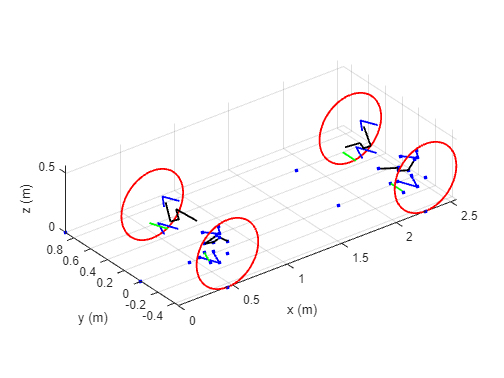

% ----------------Plotting-------------------------------------------------
figure(1)
% Plotting all points for control arms
scatter3(coords,"X","Y","Z",'filled','SizeData',hardpointsize,'Marker','o','MarkerFaceColor','blue');
hold on
% scatter3(coords(8:end,x), -coords(8:end,y), coords(8:end,z), hardpointsize, 'filled', 'o', 'blue');

% Drawing lines for front right UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(F_LCA(:,x), F_LCA(:,y), F_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(F_UCA(:,x), F_UCA(:,y), F_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(F_PR(:,x), F_PR(:,y), F_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(F_R(:,x), F_R(:,y), F_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_S(:,x), F_S(:,y), F_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_TR(:,x), F_TR(:,y), F_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Drawing lines for front left UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(F_LCA(:,x), -F_LCA(:,y), F_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(F_UCA(:,x), -F_UCA(:,y), F_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(F_PR(:,x), -F_PR(:,y), F_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(F_R(:,x), -F_R(:,y), F_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_S(:,x), -F_S(:,y), F_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_TR(:,x), -F_TR(:,y), F_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Drawing lines for rear right UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(R_LCA(:,x), R_LCA(:,y), R_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(R_UCA(:,x), R_UCA(:,y), R_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(R_PR(:,x), R_PR(:,y), R_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(R_R(:,x), R_R(:,y), R_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_S(:,x), R_S(:,y), R_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_TR(:,x), R_TR(:,y), R_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Drawing lines for rear left UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(R_LCA(:,x), -R_LCA(:,y), R_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(R_UCA(:,x), -R_UCA(:,y), R_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(R_PR(:,x), -R_PR(:,y), R_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(R_R(:,x), -R_R(:,y), R_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_S(:,x), -R_S(:,y), R_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_TR(:,x), -R_TR(:,y), R_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Drawing tires
plot3(F_W(1,:),F_W(2,:),F_W(3,:), 'Color', 'red', 'LineWidth', LineWidth)
plot3(F_W(1,:),-F_W(2,:),F_W(3,:), 'Color', 'red', 'LineWidth', LineWidth)
plot3(R_W(1,:),R_W(2,:),R_W(3,:), 'Color', 'red', 'LineWidth', LineWidth)
plot3(R_W(1,:),-R_W(2,:),R_W(3,:), 'Color', 'red', 'LineWidth', LineWidth)

% Labelling axes and setting their aspect ratio
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
axis equal


% Labelling each point in the plot
% text(coordinates(2:17,x), coordinates(2:17,y), coordinates(2:17,z), labels, 'HorizontalAlignment','center', 'VerticalAlignment','bottom');
% Labelling Moment Center separately
% text(coordinates(x,14), coordinates(y,14), coordinates(z,14), 'MomCent', 'HorizontalAlignment','center', 'VerticalAlignment','top');

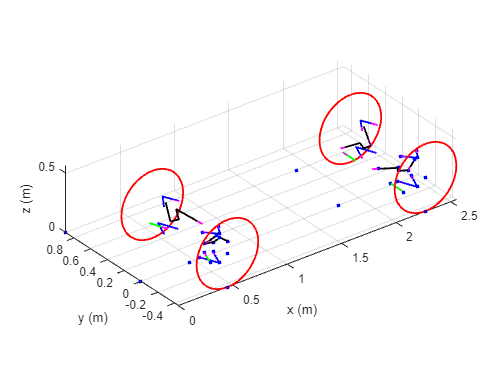

% ----------------Calculating unit vectors of member];s-----------------------
% Reflection matrix for reflecting vectors about X-Z plane
reflectY = [1 0 0; 0 -1 0; 0 0 1];

% getting unit vectors along each member
% (inboard - outboard coordinates) / magnitude
u_FL_LCA_F = (F_LCA_O-F_LCA_IF)/(norm(F_LCA_O-F_LCA_IF)); % the same as "n" shown in the matrix A
u_FL_LCA_R = (F_LCA_O-F_LCA_IR)/(norm(F_LCA_O-F_LCA_IR));
u_FL_UCA_F = (F_UCA_O-F_UCA_IF)/(norm(F_UCA_O-F_UCA_IF));
u_FL_UCA_R = (F_UCA_O-F_UCA_IR)/(norm(F_UCA_O-F_UCA_IR));
u_FL_PR = (F_PR_O-F_PR_I)/(norm(F_PR_O-F_PR_I));
u_FL_S = (F_SC-F_RS)/(norm(F_SC-F_RS));
u_FL_TR = (F_TR_O-F_TR_I)/(norm(F_TR_O-F_TR_I));

u_FR_LCA_F = u_FL_LCA_F*reflectY;
u_FR_LCA_R = u_FL_LCA_R*reflectY;
u_FR_UCA_F = u_FL_UCA_F*reflectY;
u_FR_UCA_R = u_FL_UCA_R*reflectY;
u_FR_PR = u_FL_PR*reflectY;
u_FR_S = u_FL_S*reflectY;
u_FR_TR = u_FL_TR*reflectY;

u_RL_LCA_F = (R_LCA_O-R_LCA_IF)/(norm(R_LCA_O-R_LCA_IF)); % the same as "n" shown in the matrix A
u_RL_LCA_R = (R_LCA_O-R_LCA_IR)/(norm(R_LCA_O-R_LCA_IR));
u_RL_UCA_F = (R_UCA_O-R_UCA_IF)/(norm(R_UCA_O-R_UCA_IF));
u_RL_UCA_R = (R_UCA_O-R_UCA_IR)/(norm(R_UCA_O-R_UCA_IR));
u_RL_PR = (R_PR_O-R_PR_I)/(norm(R_PR_O-R_PR_I));
u_RL_S = (R_SC-R_RS)/(norm(R_SC-R_RS));
u_RL_TR = (R_TR_O-R_TR_I)/(norm(R_TR_O-R_TR_I));

u_RR_LCA_F = u_RL_LCA_F*reflectY;
u_RR_LCA_R = u_RL_LCA_R*reflectY;
u_RR_UCA_F = u_RL_UCA_F*reflectY;
u_RR_UCA_R = u_RL_UCA_R*reflectY;
u_RR_PR = u_RL_PR*reflectY;
u_RR_S = u_RL_S*reflectY;
u_RR_TR = u_RL_TR*reflectY;

% plotting unit vectors for front members
quiver3(F_LCA_IF(x), F_LCA_IF(y), F_LCA_IF(z), u_FL_LCA_F(x), u_FL_LCA_F(y), u_FL_LCA_F(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_LCA_IR(x), F_LCA_IR(y), F_LCA_IR(z), u_FL_LCA_R(x), u_FL_LCA_R(y), u_FL_LCA_R(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_UCA_IF(x), F_UCA_IF(y), F_UCA_IF(z), u_FL_UCA_F(x), u_FL_UCA_F(y), u_FL_UCA_F(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_UCA_IR(x), F_UCA_IR(y), F_UCA_IR(z), u_FL_UCA_R(x), u_FL_UCA_R(y), u_FL_UCA_R(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_PR_I(x), F_PR_I(y), F_PR_I(z), u_FL_PR(x), u_FL_PR(y), u_FL_PR(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_SC(x), F_SC(y), F_SC(z), u_FL_S(x), u_FL_S(y), u_FL_S(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_TR_I(x), F_TR_I(y), F_TR_I(z), u_FL_TR(x), u_FL_TR(y), u_FL_TR(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);

quiver3(F_LCA_IF(x), -F_LCA_IF(y), F_LCA_IF(z), u_FR_LCA_F(x), u_FR_LCA_F(y), u_FR_LCA_F(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_LCA_IR(x), -F_LCA_IR(y), F_LCA_IR(z), u_FR_LCA_R(x), u_FR_LCA_R(y), u_FR_LCA_R(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_UCA_IF(x), -F_UCA_IF(y), F_UCA_IF(z), u_FR_UCA_F(x), u_FR_UCA_F(y), u_FR_UCA_F(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_UCA_IR(x), -F_UCA_IR(y), F_UCA_IR(z), u_FR_UCA_R(x), u_FR_UCA_R(y), u_FR_UCA_R(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_PR_I(x), -F_PR_I(y), F_PR_I(z), u_FR_PR(x), u_FR_PR(y), u_FR_PR(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_SC(x), -F_SC(y), F_SC(z), u_FR_S(x), u_FR_S(y), u_FR_S(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_TR_I(x), -F_TR_I(y), F_TR_I(z), u_FR_TR(x), u_FR_TR(y), u_FR_TR(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);

% plotting unit vectors for rear members
quiver3(R_LCA_IF(x), R_LCA_IF(y), R_LCA_IF(z), u_RL_LCA_F(x), u_RL_LCA_F(y), u_RL_LCA_F(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_LCA_IR(x), R_LCA_IR(y), R_LCA_IR(z), u_RL_LCA_R(x), u_RL_LCA_R(y), u_RL_LCA_R(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_UCA_IF(x), R_UCA_IF(y), R_UCA_IF(z), u_RL_UCA_F(x), u_RL_UCA_F(y), u_RL_UCA_F(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_UCA_IR(x), R_UCA_IR(y), R_UCA_IR(z), u_RL_UCA_R(x), u_RL_UCA_R(y), u_RL_UCA_R(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_PR_I(x), R_PR_I(y), R_PR_I(z), u_RL_PR(x), u_RL_PR(y), u_RL_PR(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_SC(x), R_SC(y), R_SC(z), u_RL_S(x), u_RL_S(y), u_RL_S(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_TR_I(x), R_TR_I(y), R_TR_I(z), u_RL_TR(x), u_RL_TR(y), u_RL_TR(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);

quiver3(R_LCA_IF(x), -R_LCA_IF(y), R_LCA_IF(z), u_RR_LCA_F(x), u_RR_LCA_F(y), u_RR_LCA_F(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_LCA_IR(x), -R_LCA_IR(y), R_LCA_IR(z), u_RR_LCA_R(x), u_RR_LCA_R(y), u_RR_LCA_R(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_UCA_IF(x), -R_UCA_IF(y), R_UCA_IF(z), u_RR_UCA_F(x), u_RR_UCA_F(y), u_RR_UCA_F(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_UCA_IR(x), -R_UCA_IR(y), R_UCA_IR(z), u_RR_UCA_R(x), u_RR_UCA_R(y), u_RR_UCA_R(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_PR_I(x), -R_PR_I(y), R_PR_I(z), u_RR_PR(x), u_RR_PR(y), u_RR_PR(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_SC(x), -R_SC(y), R_SC(z), u_RR_S(x), u_RR_S(y), u_RR_S(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_TR_I(x), -R_TR_I(y), R_TR_I(z), u_RR_TR(x), u_RR_TR(y), u_RR_TR(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);

% ----------------Calculating Moments--------------------------------------

% getting moment arm from MomCent for each member
d_FL_LCA_IR = F_LCA_IR-MC;
d_FL_LCA_IF = F_LCA_IF-MC;
d_FL_UCA_IR = F_UCA_IR-MC;
d_FL_UCA_IF = F_UCA_IF-MC;
d_FL_TR = F_TR_I-MC;
d_FL_PR = F_PR_I-MC;
d_FL_TP = F_TP-MC;

% Reflect FL in y to get FR
d_FR_LCA_IR = d_FL_LCA_IR*reflectY;
d_FR_LCA_IF = d_FL_LCA_IF*reflectY;
d_FR_UCA_IR = d_FL_UCA_IF*reflectY;
d_FR_UCA_IF = d_FL_UCA_IF*reflectY;
d_FR_TR = d_FL_TR*reflectY;
d_FR_PR = d_FL_PR*reflectY;
d_FR_TP = d_FL_TP*reflectY;

d_RL_LCA_IR = R_LCA_IR-MC;
d_RL_LCA_IF = R_LCA_IF-MC;
d_RL_UCA_IR = R_UCA_IR-MC;
d_RL_UCA_IF = R_UCA_IF-MC;
d_RL_TR = R_TR_I-MC;
d_RL_PR = R_PR_I-MC;
d_RL_TP = R_TP-MC;

% Reflect RL in y to get RR
d_RR_LCA_IR = d_RL_LCA_IR*reflectY;
d_RR_LCA_IF = d_RL_LCA_IF*reflectY;
d_RR_UCA_IR = d_RL_UCA_IF*reflectY;
d_RR_UCA_IF = d_RL_UCA_IF*reflectY;
d_RR_TR = d_RL_TR*reflectY;
d_RR_PR = d_RL_PR*reflectY;
d_RR_TP = d_RL_TP*reflectY;

% Moments for each member about the moment center
M_FL_UCA_IF = cross(d_FL_UCA_IF, u_FL_UCA_F);
M_FL_UCA_IR = cross(d_FL_UCA_IR, u_FL_UCA_R);
M_FL_LCA_IF = cross(d_FL_LCA_IF, u_FL_LCA_F);
M_FL_LCA_IR = cross(d_FL_LCA_IR, u_FL_LCA_R);
M_FL_PR = cross(d_FL_PR, u_FL_PR);
M_FL_TR = cross(d_FL_TR, u_FL_TR);

M_FR_UCA_IF = cross(d_FR_UCA_IF, u_FR_UCA_F);
M_FR_UCA_IR = cross(d_FR_UCA_IR, u_FR_UCA_R);
M_FR_LCA_IF = cross(d_FR_LCA_IF, u_FR_LCA_F);
M_FR_LCA_IR = cross(d_FR_LCA_IR, u_FR_LCA_R);
M_FR_PR = cross(d_FR_PR, u_FR_PR);
M_FR_TR = cross(d_FR_TR, u_FR_TR);

M_RL_UCA_IF = cross(d_RL_UCA_IF, u_RL_UCA_F);
M_RL_UCA_IR = cross(d_RL_UCA_IR, u_RL_UCA_R);
M_RL_LCA_IF = cross(d_RL_LCA_IF, u_RL_LCA_F);
M_RL_LCA_IR = cross(d_RL_LCA_IR, u_RL_LCA_R);
M_RL_PR = cross(d_RL_PR, u_RL_PR);
M_RL_TR = cross(d_RL_TR, u_RL_TR);

M_RR_UCA_IF = cross(d_RR_UCA_IF, u_RR_UCA_F);
M_RR_UCA_IR = cross(d_RR_UCA_IR, u_RR_UCA_R);
M_RR_LCA_IF = cross(d_RR_LCA_IF, u_RR_LCA_F);
M_RR_LCA_IR = cross(d_RR_LCA_IR, u_RR_LCA_R);
M_RR_PR = cross(d_RR_PR, u_RR_PR);
M_RR_TR = cross(d_RR_TR, u_RR_TR);

## Force Calculation

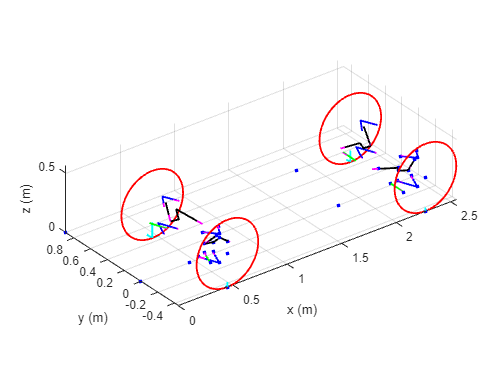

% Plotting x,y,z components of contact patch force
quiver3(F_TP(x), F_TP(y), F_TP(z), f_FL_TP(x), 0, 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(F_TP(x), F_TP(y), F_TP(z), 0, f_FL_TP(y), 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(F_TP(x), F_TP(y), F_TP(z), 0, 0, f_FL_TP(z), 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);

quiver3(F_TP(x), -F_TP(y), F_TP(z), f_FR_TP(x), 0, 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(F_TP(x), -F_TP(y), F_TP(z), 0, f_FR_TP(y), 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(F_TP(x), -F_TP(y), F_TP(z), 0, 0, f_FR_TP(z), 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);

quiver3(R_TP(x), R_TP(y), R_TP(z), f_RL_TP(x), 0, 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(R_TP(x), R_TP(y), R_TP(z), 0, f_RL_TP(y), 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(R_TP(x), R_TP(y), R_TP(z), 0, 0, f_RL_TP(z), 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);

quiver3(R_TP(x), -R_TP(y), R_TP(z), f_RR_TP(x), 0, 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(R_TP(x), -R_TP(y), R_TP(z), 0, f_RR_TP(y), 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(R_TP(x), -R_TP(y), R_TP(z), 0, 0, f_RR_TP(z), 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);

% Moments around moment center from input forces at tire patch
M_FL_TP_x = cross(d_FL_TP,[f_FL_TP(x); 0; 0]);
M_FL_TP_y = cross(d_FL_TP,[0; f_FL_TP(y); 0]);
M_FL_TP_z = cross(d_FL_TP,[0; 0; f_FL_TP(z)]);

M_FR_TP_x = cross(d_FR_TP,[f_FR_TP(x); 0; 0]);
M_FR_TP_y = cross(d_FR_TP,[0; f_FR_TP(y); 0]);
M_FR_TP_z = cross(d_FR_TP,[0; 0; f_FR_TP(z)]);

M_RL_TP_x = cross(d_RL_TP,[f_RL_TP(x); 0; 0]);
M_RL_TP_y = cross(d_RL_TP,[0; f_RL_TP(y); 0]);
M_RL_TP_z = cross(d_RL_TP,[0; 0; f_RL_TP(z)]);

M_RR_TP_x = cross(d_RR_TP,[f_RR_TP(x); 0; 0]);
M_RR_TP_y = cross(d_RR_TP,[0; f_RR_TP(y); 0]);
M_RR_TP_z = cross(d_RR_TP,[0; 0; f_RR_TP(z)]);

% ----------------Setting up Matrices to solve-------------------------------


% 6x6 matrix from sum of forces and sum of moments about MomCent
FL_A = [u_FL_UCA_F(x),    u_FL_UCA_R(x),     u_FL_LCA_F(x),     u_FL_LCA_R(x),     u_FL_PR(x),     u_FL_TR(x);
        u_FL_UCA_F(y),    u_FL_UCA_R(y),     u_FL_LCA_F(y),     u_FL_LCA_R(y),     u_FL_PR(y),     u_FL_TR(y);
        u_FL_UCA_F(z),    u_FL_UCA_R(z),     u_FL_LCA_F(z),     u_FL_LCA_R(z),     u_FL_PR(z),     u_FL_TR(z);
        M_FL_UCA_IF(x),   M_FL_UCA_IR(x),    M_FL_LCA_IF(x),    M_FL_LCA_IR(x),    M_FL_PR(x),     M_FL_TR(x);
        M_FL_UCA_IF(y),   M_FL_UCA_IR(y),    M_FL_LCA_IF(y),    M_FL_LCA_IR(y),    M_FL_PR(y),     M_FL_TR(y);
        M_FL_UCA_IF(z),   M_FL_UCA_IR(z),    M_FL_LCA_IF(z),    M_FL_LCA_IR(z),    M_FL_PR(z),     M_FL_TR(z)];

FR_A = [u_FR_UCA_F(x),    u_FR_UCA_R(x),     u_FR_LCA_F(x),     u_FR_LCA_R(x),     u_FR_PR(x),     u_FR_TR(x);
        u_FR_UCA_F(y),    u_FR_UCA_R(y),     u_FR_LCA_F(y),     u_FR_LCA_R(y),     u_FR_PR(y),     u_FR_TR(y);
        u_FR_UCA_F(z),    u_FR_UCA_R(z),     u_FR_LCA_F(z),     u_FR_LCA_R(z),     u_FR_PR(z),     u_FR_TR(z);
        M_FR_UCA_IF(x),   M_FR_UCA_IR(x),    M_FR_LCA_IF(x),    M_FR_LCA_IR(x),    M_FR_PR(x),     M_FR_TR(x);
        M_FR_UCA_IF(y),   M_FR_UCA_IR(y),    M_FR_LCA_IF(y),    M_FR_LCA_IR(y),    M_FR_PR(y),     M_FR_TR(y);
        M_FR_UCA_IF(z),   M_FR_UCA_IR(z),    M_FR_LCA_IF(z),    M_FR_LCA_IR(z),    M_FR_PR(z),     M_FR_TR(z)];

RL_A = [u_RL_UCA_F(x),    u_RL_UCA_R(x),     u_RL_LCA_F(x),     u_RL_LCA_R(x),     u_RL_PR(x),     u_RL_TR(x);
        u_RL_UCA_F(y),    u_RL_UCA_R(y),     u_RL_LCA_F(y),     u_RL_LCA_R(y),     u_RL_PR(y),     u_RL_TR(y);
        u_RL_UCA_F(z),    u_RL_UCA_R(z),     u_RL_LCA_F(z),     u_RL_LCA_R(z),     u_RL_PR(z),     u_RL_TR(z);
        M_RL_UCA_IF(x),   M_RL_UCA_IR(x),    M_RL_LCA_IF(x),    M_RL_LCA_IR(x),    M_RL_PR(x),     M_RL_TR(x);
        M_RL_UCA_IF(y),   M_RL_UCA_IR(y),    M_RL_LCA_IF(y),    M_RL_LCA_IR(y),    M_RL_PR(y),     M_RL_TR(y);
        M_RL_UCA_IF(z),   M_RL_UCA_IR(z),    M_RL_LCA_IF(z),    M_RL_LCA_IR(z),    M_RL_PR(z),     M_RL_TR(z)];

RR_A = [u_RR_UCA_F(x),    u_RR_UCA_R(x),     u_RR_LCA_F(x),     u_RR_LCA_R(x),     u_RR_PR(x),     u_RR_TR(x);
        u_RR_UCA_F(y),    u_RR_UCA_R(y),     u_RR_LCA_F(y),     u_RR_LCA_R(y),     u_RR_PR(y),     u_RR_TR(y);
        u_RR_UCA_F(z),    u_RR_UCA_R(z),     u_RR_LCA_F(z),     u_RR_LCA_R(z),     u_RR_PR(z),     u_RR_TR(z);
        M_RR_UCA_IF(x),   M_RR_UCA_IR(x),    M_RR_LCA_IF(x),    M_RR_LCA_IR(x),    M_RR_PR(x),     M_RR_TR(x);
        M_RR_UCA_IF(y),   M_RR_UCA_IR(y),    M_RR_LCA_IF(y),    M_RR_LCA_IR(y),    M_RR_PR(y),     M_RR_TR(y);
        M_RR_UCA_IF(z),   M_RR_UCA_IR(z),    M_RR_LCA_IF(z),    M_RR_LCA_IR(z),    M_RR_PR(z),     M_RR_TR(z)];


% Make input matrix B=[-F(x); -F(y); -F(z); -M(x); -M(y); -M(z)]
FL_B = [-f_FL_TP(x);
        -f_FL_TP(y);
        -f_FL_TP(z);
        -(M_FL_TP_x(x)+M_FL_TP_y(x)+M_FL_TP_z(x));
        -(M_FL_TP_x(y)+M_FL_TP_y(y)+M_FL_TP_z(y));
        -(M_FL_TP_x(z)+M_FL_TP_y(z)+M_FL_TP_z(z))];

FR_B = [-f_FR_TP(x);
        -f_FR_TP(y);
        -f_FR_TP(z);
        -(M_FR_TP_x(x)+M_FR_TP_y(x)+M_FR_TP_z(x));
        -(M_FR_TP_x(y)+M_FR_TP_y(y)+M_FR_TP_z(y));
        -(M_FR_TP_x(z)+M_FR_TP_y(z)+M_FR_TP_z(z))];

RL_B = [-f_RL_TP(x);
        -f_RL_TP(y);
        -f_RL_TP(z);
        -(M_RL_TP_x(x)+M_RL_TP_y(x)+M_RL_TP_z(x));
        -(M_RL_TP_x(y)+M_RL_TP_y(y)+M_RL_TP_z(y));
        -(M_RL_TP_x(z)+M_RL_TP_y(z)+M_RL_TP_z(z))];

RR_B = [-f_RR_TP(x);
        -f_RR_TP(y);
        -f_RR_TP(z);
        -(M_RR_TP_x(x)+M_RR_TP_y(x)+M_RR_TP_z(x));
        -(M_RR_TP_x(y)+M_RR_TP_y(y)+M_RR_TP_z(y));
        -(M_RR_TP_x(z)+M_RR_TP_y(z)+M_RR_TP_z(z))];


% ----------------Solve for Forces in Members------------------------------

f_FL_mag = FL_A\FL_B;
f_FR_mag = FR_A\FR_B;
f_RL_mag = RL_A\RL_B;
f_RR_mag = RR_A\RR_B;

% Formatting of f_mag: f_mag = [f_UCA_F; f_UCA_R; f_LCA_F; f_LCA_R; f_PR; f_TR]

% Each member force as a 3x1 vector
f_FL_UCA_F = f_FL_mag(1)*u_FL_UCA_F;
f_FL_UCA_R = f_FL_mag(2)*u_FL_UCA_R;
f_FL_LCA_F = f_FL_mag(3)*u_FL_LCA_F;
f_FL_LCA_R = f_FL_mag(4)*u_FL_LCA_R;
f_FL_PR = f_FL_mag(5)*u_FL_PR;
f_FL_TR = f_FL_mag(6)*u_FL_TR;

f_FR_UCA_F = f_FR_mag(1)*u_FR_UCA_F;
f_FR_UCA_R = f_FR_mag(2)*u_FR_UCA_R;
f_FR_LCA_F = f_FR_mag(3)*u_FR_LCA_F;
f_FR_LCA_R = f_FR_mag(4)*u_FR_LCA_R;
f_FR_PR = f_FR_mag(5)*u_FR_PR;
f_FR_TR = f_FR_mag(6)*u_FR_TR;

f_RL_UCA_F = f_RL_mag(1)*u_RL_UCA_F;
f_RL_UCA_R = f_RL_mag(2)*u_RL_UCA_R;
f_RL_LCA_F = f_RL_mag(3)*u_RL_LCA_F;
f_RL_LCA_R = f_RL_mag(4)*u_RL_LCA_R;
f_RL_PR = f_RL_mag(5)*u_RL_PR;
f_RL_TR = f_RL_mag(6)*u_RL_TR;

f_RR_UCA_F = f_RR_mag(1)*u_RR_UCA_F;
f_RR_UCA_R = f_RR_mag(2)*u_RR_UCA_R;
f_RR_LCA_F = f_RR_mag(3)*u_RR_LCA_F;
f_RR_LCA_R = f_RR_mag(4)*u_RR_LCA_R;
f_RR_PR = f_RR_mag(5)*u_RR_PR;
f_RR_TR = f_RR_mag(6)*u_RR_TR;

% Forces at UBJ and LBJ
f_FL_UCA_O = f_FL_UCA_F + f_FL_UCA_R + f_FL_PR;
f_FL_LCA_O = f_FL_LCA_F + f_FL_LCA_R;

f_FR_UCA_O = f_FR_UCA_F + f_FR_UCA_R + f_FR_PR;
f_FR_LCA_O = f_FR_LCA_F + f_FR_LCA_R;

f_RL_UCA_O = f_RL_UCA_F + f_RL_UCA_R + f_RL_PR;
f_RL_LCA_O = f_RL_LCA_F + f_RL_LCA_R;

f_RR_UCA_O = f_RR_UCA_F + f_RR_UCA_R + f_RR_PR;
f_RR_LCA_O = f_RR_LCA_F + f_RR_LCA_R;

% ---------------Solve for Forces in Rocker and Shock--------------------

% Moment arm from rocker pivot for pullrod and shock
d_FL_RP_PR = F_PR_I - F_RP;
d_FL_RP_RS = F_RS - F_RP;
d_FR_RP_PR = d_FL_RP_PR*reflectY;
d_FR_RP_RS = d_FL_RP_RS*reflectY;
d_RL_RP_PR = R_PR_I - R_RP;
d_RL_RP_RS = R_RS - R_RP;
d_RR_RP_PR = d_RL_RP_PR*reflectY;
d_RR_RP_RS = d_RL_RP_RS*reflectY;

% Moment about rocker pivot from pullrod input force
M_FL_RP_PR = cross(d_FL_RP_PR, f_FL_PR);
M_FR_RP_PR = cross(d_FR_RP_PR, f_FR_PR);
M_RL_RP_PR = cross(d_RL_RP_PR, f_RL_PR);
M_RR_RP_PR = cross(d_RR_RP_PR, f_RR_PR);

% Moment about rocker pivot for shock
M_FL_RP_RS = cross(d_FL_RP_RS, u_FL_S);
M_FR_RP_RS = cross(d_FR_RP_RS, u_FR_S);
M_RL_RP_RS = cross(d_RL_RP_RS, u_RL_S);
M_RR_RP_RS = cross(d_RR_RP_RS, u_RR_S);

% Setting up matrix and solving

%FL
FL_RP_A = [1 0 0 u_FL_S(x)
           0 1 0 u_FL_S(y)
           0 0 1 u_FL_S(z)
           0 0 0 M_FL_RP_RS(x)
           0 0 0 M_FL_RP_RS(y)
           0 0 0 M_FL_RP_RS(z)];
FL_RP_B = [-f_FL_PR(x); -f_FL_PR(y); -f_FL_PR(z); -M_FL_RP_PR(x); -M_FL_RP_PR(y); -M_FL_RP_PR(z)];
f_FL_RP_mag = FL_RP_A\FL_RP_B;

f_FL_RP = f_FL_RP_mag(1:3);
f_FL_S = f_FL_RP_mag(4)*u_FL_S;

% Finding axial and radial components of the rocker pivot force
n_FL_R = cross(F_R(1,:)-F_R(2,:),F_R(3,:)-F_R(2,:));
n_FL_R = (n_FL_R/norm(n_FL_R))';
f_FL_RP_radial = norm(f_FL_RP - (dot((f_FL_RP-F_R(2,:)'),n_FL_R) * n_FL_R));
f_FL_RP_axial = norm(dot((f_FL_RP-F_R(2,:)'),n_FL_R) * n_FL_R);

% Finding components of pull-rod force along rocker dims
u_FL_Rx = (F_R(3,:)-F_R(1,:))/norm(F_R(3,:)-F_R(1,:));
u_FL_Ry = cross(n_FL_R,u_FL_Rx);
f_FL_PR_Rx = dot(f_FL_PR,u_FL_Rx);
f_FL_PR_Ry = dot(f_FL_PR,u_FL_Ry);


%FR
FR_RP_A = [1 0 0 u_FR_S(x)
           0 1 0 u_FR_S(y)
           0 0 1 u_FR_S(z)
           0 0 0 M_FR_RP_RS(x)
           0 0 0 M_FR_RP_RS(y)
           0 0 0 M_FR_RP_RS(z)];
FR_RP_B = [-f_FR_PR(x); -f_FR_PR(y); -f_FR_PR(z); -M_FR_RP_PR(x); -M_FR_RP_PR(y); -M_FR_RP_PR(z)];
f_FR_RP_mag = FR_RP_A\FR_RP_B;

f_FR_RP = f_FR_RP_mag(1:3);
f_FR_S = f_FR_RP_mag(4)*u_FR_S;

% Finding axial and radial components of the rocker pivot force
n_FR_R = cross(F_R(1,:)-F_R(2,:),F_R(3,:)-F_R(2,:))*reflectY;
n_FR_R = (n_FR_R/norm(n_FR_R))';
f_FR_RP_radial = norm(f_FR_RP - (dot((f_FR_RP-(F_R(2,:)*reflectY)'),n_FR_R) * n_FR_R));
f_FR_RP_axial = norm(dot((f_FR_RP-(F_R(2,:)*reflectY)'),n_FR_R) * n_FR_R);

% Finding components of pull-rod force along rocker dims
u_FR_Rx = (F_R(3,:)-F_R(1,:))/norm(F_R(3,:)-F_R(1,:))*reflectY;
u_FR_Ry = cross(n_FR_R,u_FR_Rx);
f_FR_PR_Rx = dot(f_FR_PR,u_FR_Rx);
f_FR_PR_Ry = dot(f_FR_PR,u_FR_Ry);


%RL
RL_RP_A = [1 0 0 u_RL_S(x)
           0 1 0 u_RL_S(y)
           0 0 1 u_RL_S(z)
           0 0 0 M_RL_RP_RS(x)
           0 0 0 M_RL_RP_RS(y)
           0 0 0 M_RL_RP_RS(z)];
RL_RP_B = [-f_RL_PR(x); -f_RL_PR(y); -f_RL_PR(z); -M_RL_RP_PR(x); -M_RL_RP_PR(y); -M_RL_RP_PR(z)];
f_RL_RP_mag = RL_RP_A\RL_RP_B;

f_RL_RP = f_RL_RP_mag(1:3);
f_RL_S = f_RL_RP_mag(4)*u_RL_S;

% Finding axial and radial components of the rocker pivot force
n_RL_R = cross(R_R(1,:)-R_R(2,:),R_R(3,:)-R_R(2,:));
n_RL_R = (n_RL_R/norm(n_RL_R))';
f_RL_RP_radial = norm(f_RL_RP - (dot((f_RL_RP-R_R(2,:)'),n_RL_R) * n_RL_R));
f_RL_RP_axial = norm(dot((f_RL_RP-R_R(2,:)'),n_RL_R) * n_RL_R);


%RR
RR_RP_A = [1 0 0 u_RR_S(x)
           0 1 0 u_RR_S(y)
           0 0 1 u_RR_S(z)
           0 0 0 M_RR_RP_RS(x)
           0 0 0 M_RR_RP_RS(y)
           0 0 0 M_RR_RP_RS(z)];
RR_RP_B = [-f_RR_PR(x); -f_RR_PR(y); -f_RR_PR(z); -M_RR_RP_PR(x); -M_RR_RP_PR(y); -M_RR_RP_PR(z)];
f_RR_RP_mag = RR_RP_A\RR_RP_B;

f_RR_RP = f_RR_RP_mag(1:3);
f_RR_S = f_RR_RP_mag(4)*u_RR_S;

% Finding axial and radial components of the rocker pivot force
n_RR_R = cross(R_R(1,:)-R_R(2,:),R_R(3,:)-R_R(2,:))*reflectY;
n_RR_R = (n_RR_R/norm(n_RR_R))';
f_RR_RP_radial = norm(f_RR_RP - (dot((f_RR_RP-(R_R(2,:)*reflectY)'),n_RR_R) * n_RR_R));
f_RR_RP_axial = norm(dot((f_RR_RP-(R_R(2,:)*reflectY)'),n_RR_R) * n_RR_R);


f_Out = cell2table({    "FL" "UCA Front" f_FL_UCA_F; 
                        "FL" "UCA Rear" f_FL_UCA_R;
                        "FL" "UCA Balljoint" f_FL_UCA_O; 
                        "FL" "LCA Front" f_FL_LCA_F;
                        "FL" "LCA Rear" f_FL_LCA_R;
                        "FL" "LCA Balljoint" f_FL_LCA_O;
                        "FL" "Pullrod" f_FL_PR;
                        "FL" "Pullrod along rocker" [f_FL_PR_Rx f_FL_PR_Ry 0];
                        "FL" "Rocker pivot" f_FL_RP';
                        "FL" "Rocker pivot radial/axial" [f_FL_RP_radial f_FL_RP_axial 0]; 
                        "FL" "Shock" f_FL_S;
                        "FL" "Steering Tie-rod" f_FL_TR;

                        "FR" "UCA Front" f_FR_UCA_F; 
                        "FR" "UCA Rear" f_FR_UCA_R;
                        "FR" "UCA Balljoint" f_FR_UCA_O; 
                        "FR" "LCA Front" f_FR_LCA_F;
                        "FR" "LCA Rear" f_FR_LCA_R;
                        "FR" "LCA Balljoint" f_FR_LCA_O;
                        "FR" "Pullrod" f_FR_PR;
                        "FR" "Pullrod along rocker" [f_FR_PR_Rx f_FR_PR_Ry 0];
                        "FR" "Rocker pivot" f_FR_RP';
                        "FR" "Rocker pivot radial/axial" [f_FR_RP_radial f_FR_RP_axial 0]; 
                        "FR" "Shock" f_FR_S;
                        "FR" "Steering Tie-rod" f_FR_TR;
            
                        "RL" "UCA Front" f_RL_UCA_F; 
                        "RL" "UCA Rear" f_RL_UCA_R;
                        "RL" "UCA Balljoint" f_RL_UCA_O; 
                        "RL" "LCA Front" f_RL_LCA_F;
                        "RL" "LCA Rear" f_RL_LCA_R;
                        "RL" "LCA Balljoint" f_RL_LCA_O;
                        "RL" "Pullrod" f_RL_PR;
                        "RL" "Rocker pivot" f_RL_RP';
                        "RL" "Rocker pivot radial/axial" [f_RL_RP_radial f_RL_RP_axial 0]; 
                        "RL" "Shock" f_RL_S;
                        "RL" "Steering Tie-rod" f_RL_TR;
            
                        "RR" "UCA Front" f_RR_UCA_F; 
                        "RR" "UCA Rear" f_RR_UCA_R;
                        "RR" "UCA Balljoint" f_RR_UCA_O; 
                        "RR" "LCA Front" f_RR_LCA_F;
                        "RR" "LCA Rear" f_RR_LCA_R;
                        "RR" "LCA Balljoint" f_RR_LCA_O;
                        "RR" "Pullrod" f_RR_PR;
                        "RR" "Rocker pivot" f_RR_RP';
                        "RR" "Rocker pivot radial/axial" [f_RR_RP_radial f_RR_RP_axial 0]; 
                        "RR" "Shock" f_RR_S;
                        "RR" "Steering Tie-rod" f_RR_TR                                   },...
                        'VariableNames',{'Wheel','Member','Force'});

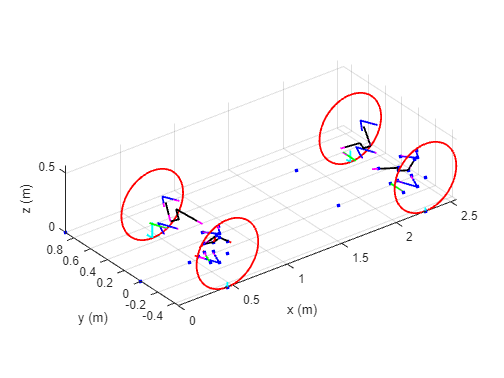

% ----------------Plotting Force vectors for Members-----------------------


% plotting Force vector along bottom front member
quiver3(F_LCA_IF(x), F_LCA_IF(y), F_LCA_IF(z), f_FL_LCA_F(x), f_FL_LCA_F(y), f_FL_LCA_F(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along bottom rear member
quiver3(F_LCA_IR(x), F_LCA_IR(y), F_LCA_IR(z), f_FL_LCA_R(x), f_FL_LCA_R(y), f_FL_LCA_R(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along top front member
quiver3(F_UCA_IF(x), F_UCA_IF(y), F_UCA_IF(z), f_FL_UCA_F(x), f_FL_UCA_F(y), f_FL_UCA_F(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along top rear member
quiver3(F_UCA_IR(x), F_UCA_IR(y), F_UCA_IR(z), f_FL_UCA_R(x), f_FL_UCA_R(y), f_FL_UCA_R(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along shock member
quiver3(F_PR_I(x), F_PR_I(y), F_PR_I(z), f_FL_PR(x), f_FL_PR(y), f_FL_PR(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along tie rod
quiver3(F_TR_I(x), F_TR_I(y), F_TR_I(z), f_FL_TR(x), f_FL_TR(y), f_FL_TR(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along pull rod
quiver3(F_PR_I(x), F_PR_I(y), F_PR_I(z), f_FL_PR(x), f_FL_PR(y), f_FL_PR(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector for rocker pivot
quiver3(F_RP(x), F_RP(y), F_RP(z), f_FL_RP(x), f_FL_RP(y), f_FL_RP(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along shock
quiver3(F_SC(x), F_SC(y), F_SC(z), f_FL_S(x), f_FL_S(y), f_FL_S(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);